gpu = gpuDevice();
fprintf('Using a %s GPU.\n', gpu.Name)

Using a GeForce GTX 1050 GPU.



video = VideoReader('./examples/test3.mp4');
aGray = uint8([]);
%class(aGray)

I_BG = gpuArray(im2uint8(rgb2gray(readFrame(video))));
k = 1;
while hasFrame(video)
    % im2uint8(rgb2gray(readFrame(video)))
    % frame = rgb2gray(readFrame(video))
    % g = gpuArray(frame);
    aGray(:, :, k) = im2uint8(rgb2gray(readFrame(video)));
    k = k+1;
end

%implay(aGray)

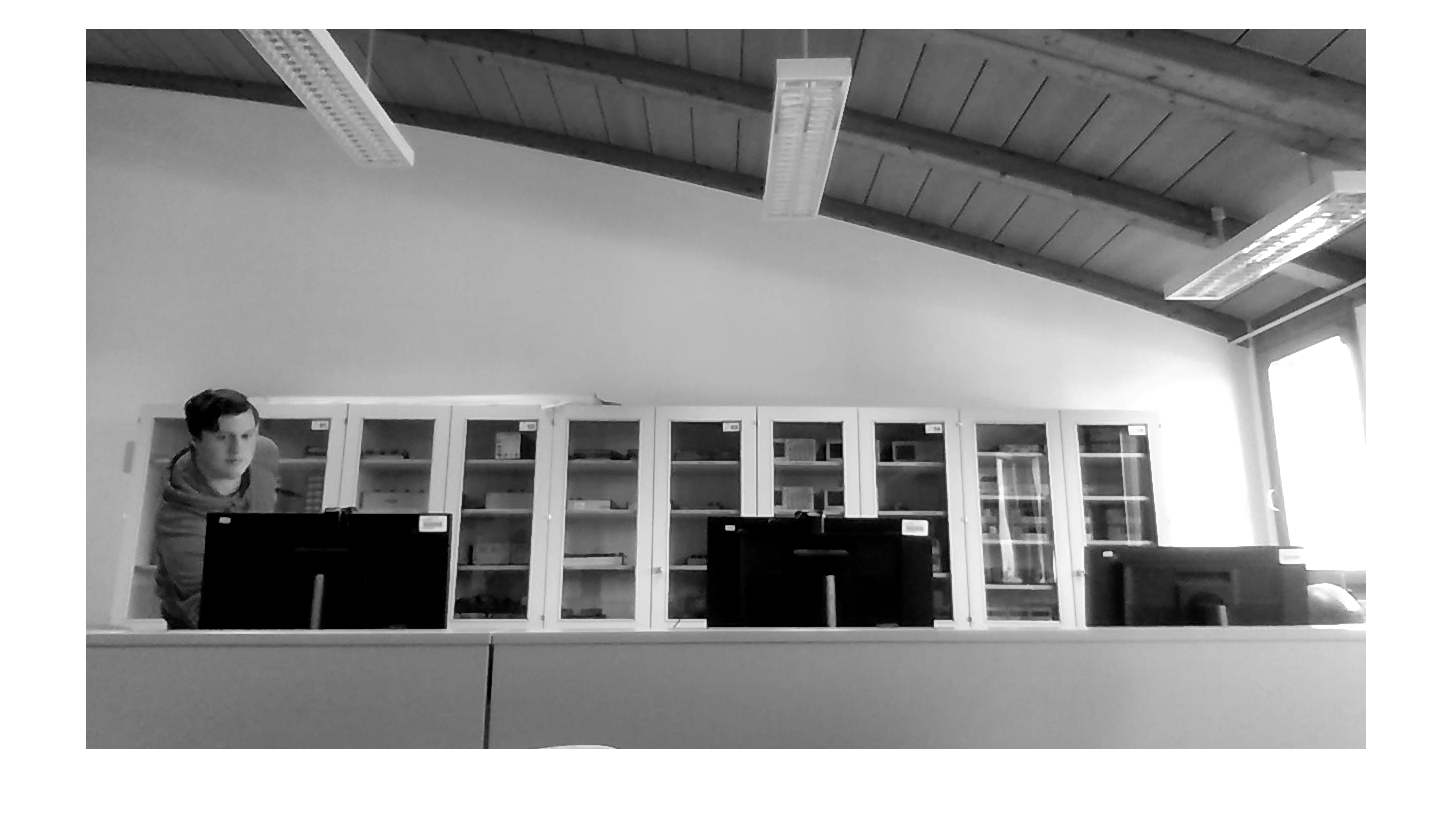

imshow(I_BG);

aDiff = int8([]);

for i = 1:(k-1)
    gArray = gpuArray(aGray)
    I_diff = imabsdiff(gArray(:,:,i), I_BG);
    aDiff(:,:,end+1) = gather(I_diff);
end


gArray(:,:,1) = <page truncated: showing [1:24, 1:43] of 720-by-1280>

  Columns 1 through 31

   70   70   73   73   74   73   72   70   69   67   65   63   60   62   64   66   69   69   69   69   71   70   71   71   69   69   69   69   69   70   70
   70   70   73   73   74   73   72   70   70   67   65   64   62   63   64   65   68   69   69   69   70   70   70   70   69   69   69   69   69   70   70
   70   70   72   73   73   72   72   72   72   70   68   66   66   65   64   63   66   67   67   67   69   69   69   69   68   67   69   69   69   70   70
   70   71   70   73   73   73   72   73   73   71   69   69   70   68   64   62   64   63   67   67   69   69   68   68   68   67   69   70   69   70   70
   70   70   71   70   71   72   73   73   71   71   71   71   71   69   65   62   62   62   65   67   67   67   67   67   66   67   67   69   69   69   69
   70   70   70   70   71   70   71   72   72   71   71   71   72   68   66   65   63   63   63   63   64   65   66   66   6

%implay(aDiff)

T_thresh = 100;
vCount = [];

for i = 1:(k-1)
    [w, h] = size(aDiff(:, :, i));
    frame = aDiff(:, :, i)>T_thresh;
    c = nnz(frame);
    
    [minRow, minCol] = find(frame == true, 1 );
    [maxRow, maxCol] = find(frame == true, 1, 'last');
    
    pos = [minRow, minCol, maxRow, maxCol];
    
    c_rel = c / (w*h);
    vCount(end+1) = c_rel;
end

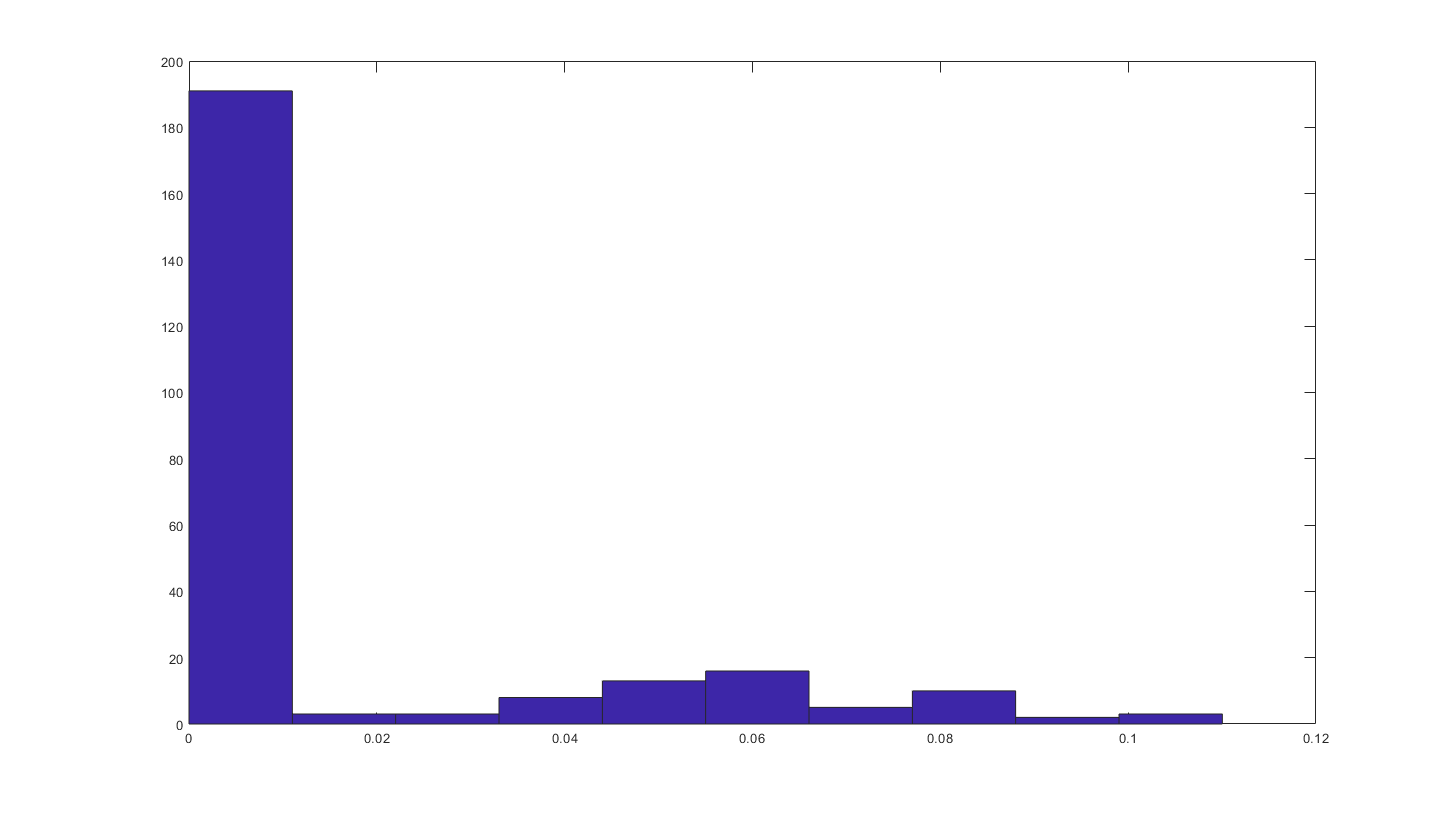

hist(vCount)

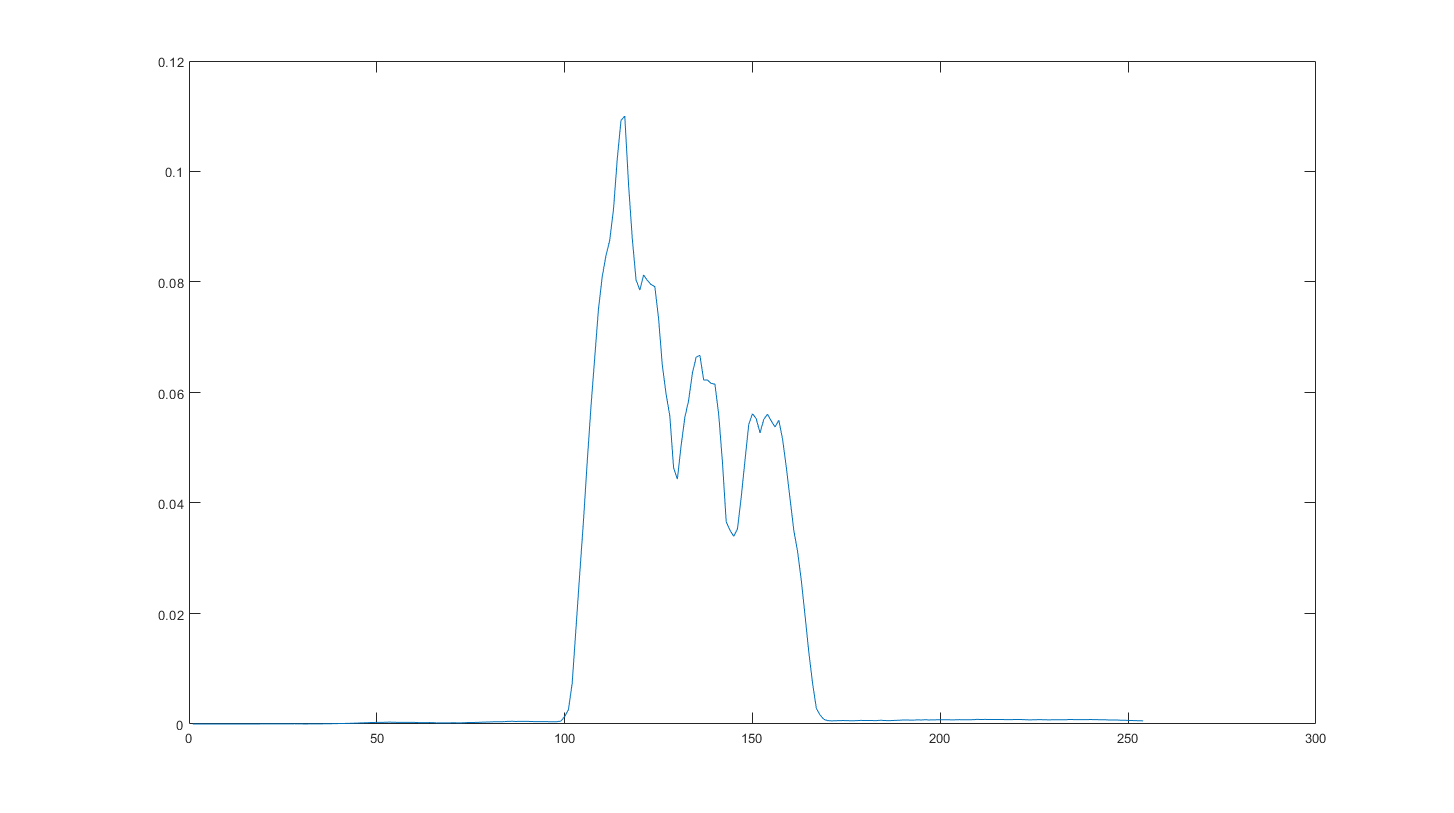

plot(1:length(vCount) ,vCount)

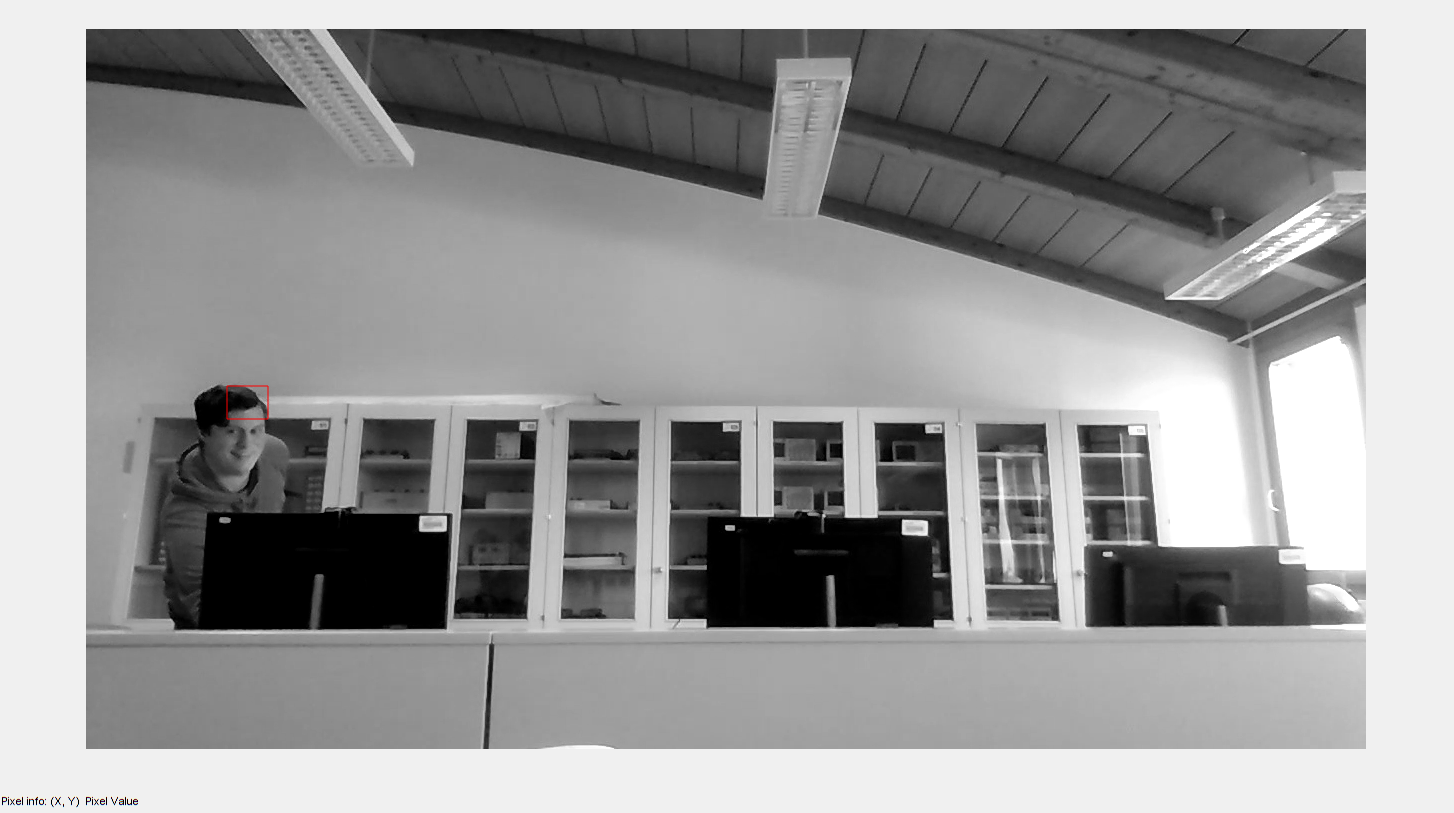

figure,
for i = 2:(k-1)
    T_thresh = 76;
    imdiff = aDiff(:, :, i)>T_thresh;
    %y = nnz(x);
    imLabel = bwlabel(bwfill(bwpropfilt(imdiff, 'Area', [200 5000]), 'holes'), 8);

    box = regionprops(logical(imLabel), 'BoundingBox');
    n = label2rgb(imLabel, 'prism', 'k');
    s = size(box);
    
    imshow(aGray(:, :, i)), impixelinfo, hold on
    drawnow;

    x1 = [];
    y1 = [];
    x2 = [];
    y2 = [];
    for d = 1:s(1)
        p = box(d).BoundingBox;
        x1(end+1) = p(1);
        y1(end+1) = p(2);
        x2(end+1) = p(1) + p(3);
        y2(end+1) = p(2) + p(4);
    end
    x = min(x1);
    y = min(y1);
    w = max(x2) - x;
    h = max(y2) - y;

    try
        rectangle('Position', [x,y,w,h],'EdgeColor','r');
    catch ME
        rectangle('Position', [0, 0, 0, 0],'EdgeColor','r');
    end
end